% generate wav


fBegin = 2000;
fEnd = 6000;
frequencyOfSample = 44100

frequencyOfSample = 44100

chirpTimeMs = 50   %ms

chirpTimeMs = 50

prepareTimeMs = 50

prepareTimeMs = 50


chirpSample = floor(chirpTimeMs * frequencyOfSample / 1000)

chirpSample = 2205

prepareSample = floor(prepareTimeMs * frequencyOfSample / 1000)

prepareSample = 2205


t1 = (0:prepareSample - 1) / frequencyOfSample

t1 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


y1 = sin(2 * pi * fBegin * t1)

y1 =          0    0.2811    0.5396    0.7545    0.9086    0.9894    0.9904    0.9115    0.7591    0.5455    0.2879    0.0071   -0.2743   -0.5335   -0.7498   -0.9056   -0.9883   -0.9913   -0.9144   -0.7638   -0.5515   -0.2948   -0.0142    0.2674    0.5275    0.7450    0.9025    0.9872    0.9922    0.9173    0.7683    0.5574    0.3016    0.0214   -0.2605   -0.5214   -0.7403   -0.8994   -0.9860   -0.9931   -0.9201   -0.7729   -0.5633   -0.3083   -0.0285    0.2537    0.5153    0.7355    0.8963    0.9848



t2 = (0:chirpSample) / frequencyOfSample

t2 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


k = (fEnd - fBegin) * 1000 / chirpTimeMs

k = 80000

y2 = sin(2 * pi * (fBegin * t2 + 1/2 * k * t2 .* t2))

y2 =          0    0.2812    0.5400    0.7552    0.9094    0.9898    0.9897    0.9089    0.7537    0.5367    0.2755   -0.0085   -0.2921   -0.5519   -0.7663   -0.9175   -0.9928   -0.9857   -0.8967   -0.7328   -0.5077   -0.2398    0.0483    0.3326    0.5892    0.7964    0.9366    0.9978    0.9746    0.8687    0.6889    0.4503    0.1731   -0.1191   -0.4013   -0.6494   -0.8420   -0.9623   -0.9998   -0.9511   -0.8201   -0.6179   -0.3620   -0.0744    0.2199    0.4953    0.7276    0.8965    0.9869    0.9908



t = [t1, t2 + prepareSample / frequencyOfSample]

t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


y = [y1, y2]

y =          0    0.2811    0.5396    0.7545    0.9086    0.9894    0.9904    0.9115    0.7591    0.5455    0.2879    0.0071   -0.2743   -0.5335   -0.7498   -0.9056   -0.9883   -0.9913   -0.9144   -0.7638   -0.5515   -0.2948   -0.0142    0.2674    0.5275    0.7450    0.9025    0.9872    0.9922    0.9173    0.7683    0.5574    0.3016    0.0214   -0.2605   -0.5214   -0.7403   -0.8994   -0.9860   -0.9931   -0.9201   -0.7729   -0.5633   -0.3083   -0.0285    0.2537    0.5153    0.7355    0.8963    0.9848


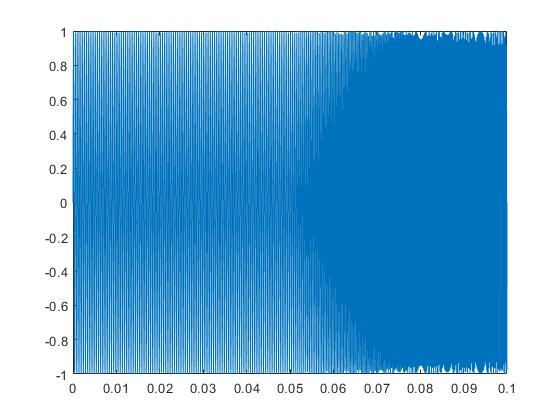


plot(t, y)

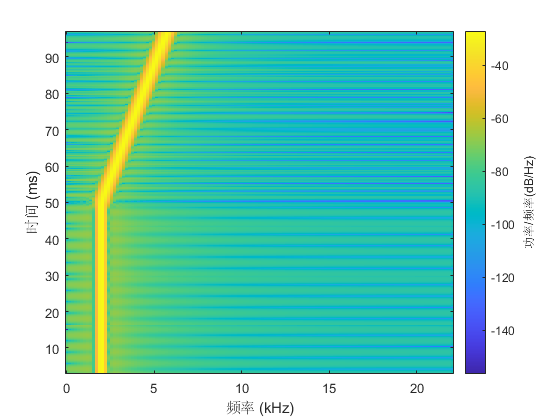


spectrogram(y, 256, 250, 256, 44100)


fName = "chirp_for_experiment.wav"

fName = "chirp_for_experiment.wav"

audiowrite(fName, y, frequencyOfSample)
info = audioinfo(fName)

info = 包含以下字段的 struct :
             Filename: 'D:\WorkSpace\IDEA\beepbeep-server\matlab\chirp_for_experiment.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 4411
             Duration: 0.1000
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16
